# Rock vs No Rock: Data recording sheet

**Author: **Ross Wilkinson

**University: **University of Colorado Boulder

## Testing information

- Experiment: Rock vs No Rock

- Objective: Test effect of bicycle lean on maximal power output 

- Date: July 20, 2020

- Location: Locomotion Laboratory

- Subject: SX

- Quarq calibration factor: 234

## Experimental setup

### Protocol reminders

- Charge Garmin, iPad, and IMUs

- Clarify participant understanding and answer questions

- Set saddle height and handlebar position

- Sanitize bicycle

- Calibrate power meter

- Setup cooling fan

- Gift card and signature

### Experimental conditions

- Preferred Lean

- Self-restricted

- Locked

### Trial order

- Warm up: 5 min at ~100 W (3.5 lb)

- Familiarization: Standing and leaning (8.5 lb)

- Pmax Test: 3 x hanging weights under condition 1

- Block 1: Randomize

- Block 2: Randomize

- Block 3: Randomize

### Environmental conditions

- Temperature (C): 21

- Humidity (%): 48

- Pressure (mmHg): 638

- Altitude (m): 1641

### Subject characteristics

Record subject characteristics to table for group data analysis.

number = 1;
code = {'SX'};
sex = {'M'};
age = 33;
mass = 172; %lb
height = 1.78; %m

T = table(number,code,sex,age,mass,height)

T = 1×6 table
    num     code      sex     age     Var5     height
    ___    ______    _____    ___    ______    ______

     1     {'SX'}    {'M'}    33     78.005     1.78 


## Results

Use mass to calculate individualised hanging weights for Pmax Test.

listPerc = [0.06; 0.12; 0.18];
listHang = listPerc * mass

listHang =    10.3200
   20.6400
   30.9600


### Pmax test

Record Pmax test results. Fit curve to predict optimal hanging weight.

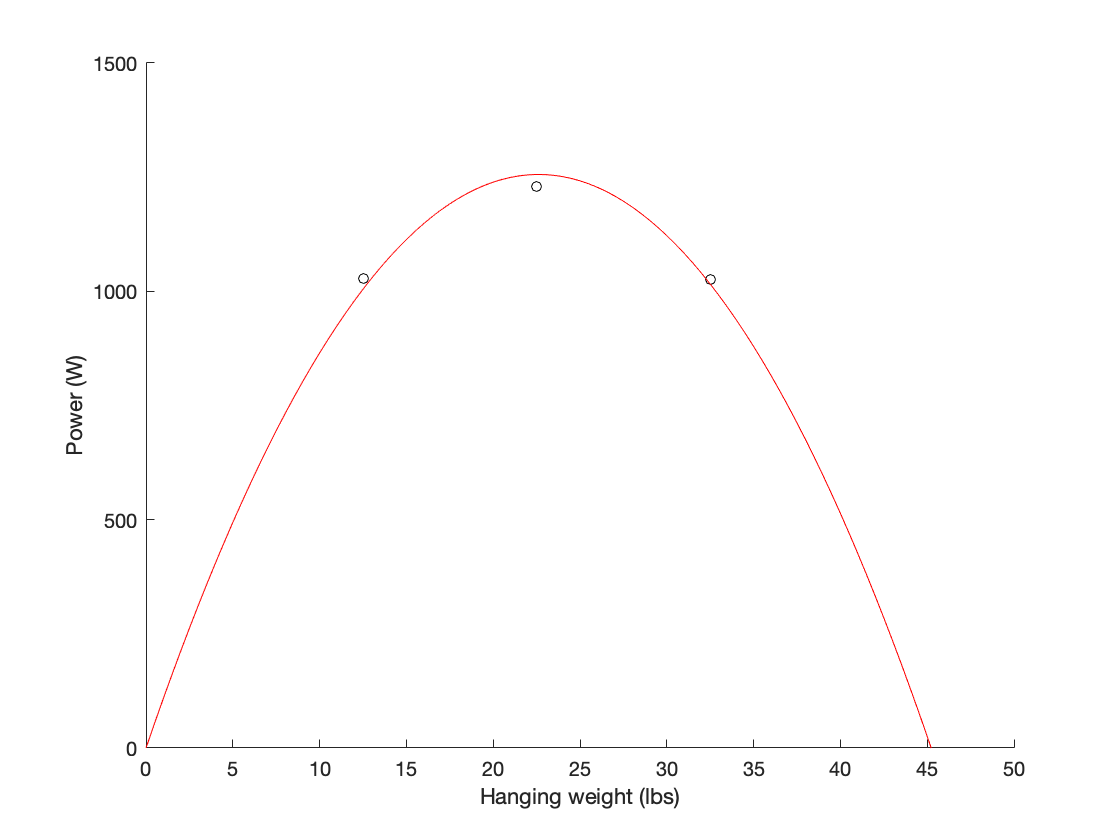

x = [12.5;22.5;32.5]; % hanging weight
x_ = [166; 115; 70]; % cadence
y = [1028; 1230; 1025]; % power output

% fit curve: power vs hang
[c, ~, ~] = fit(x,y,'poly2','Lower',[-Inf -Inf 0],'Upper',[Inf Inf 0]);

new_x = 0:50/100:50;
new_y = c.p1*new_x.^2+c.p2*new_x+c.p3;

% plot curve: power vs hang
scatter(x,y,25,'k');
hold on
plot(new_x,new_y,'r-')

% edit figure
box off
xlabel('Hanging weight (lbs)')
ylabel('Power (W)')
xlim([0 50])
ylim([0 max(y)*1.2])


% find optimal x and y
[yOpt,I] = max(new_y);
xOpt = new_x(I);

fprintf('Predicted maximal power output = %4.2f Watts \n', yOpt)

Predicted maximal power output = 1255.91 Watts 


fprintf('Predicted optimal hanging weight = %4.2f Lbs \n', xOpt)

Predicted optimal hanging weight = 22.50 Lbs 


### Randomize trial order within each block

randperm(3)

ans =      1     2     3


randperm(3)

ans =      2     1     3


randperm(3)

ans =      3     2     1


### Experimental results

Record results to array then convert to table.

data = [
    1, 3, 1, 22.5, 1392, 116;
    1, 1, 1, 22.5, 1309, 114;
    1, 2, 1, 22.5, 1332, 114;
    1, 1, 2, 22.5, 1366, 117;
    1, 2, 2, 22.5, 1320, 111;
    1, 3, 2, 22.5, 1428, 119;
    1, 2, 3, 22.5, 1297, 117;
    1, 1, 3, 22.5, 1358, 115;
    1, 3, 3, 22.5, 1407, 120;
    ];

T_ = array2table(data, ...
    'VariableNames',{'subject','condition','trial','hangingWeight','power','cadence'})

T_ = 9×6 table
    subject    condition    trial    hangingWeight    power    cadence
    _______    _________    _____    _____________    _____    _______

       1           3          1          22.5         1392       116  
       1           1          1          22.5         1309       114  
       1           2          1          22.5         1332       114  
       1           1          2          22.5         1366       117  
       1           2          2          22.5         1320       111  
       1           3          2          22.5         1428       119  
       1           2          3          22.5         1297       117  
       1           1          3          22.5         1358       115  
       1           3          3          22.5         1407       120  

## Data analysis

Calculate mean and SD power and cadence for experimental trials.

varfun(@mean,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    mean_power    mean_cadence
    _________    __________    __________    ____________

        1            3           1344.3         115.33   
        2            3           1316.3            114   
        3            3             1409         118.33   


varfun(@std,T_,'InputVariables',{'power','cadence'}, ...
    'GroupingVariables',{'condition'})

ans = 3×4 table
    condition    GroupCount    std_power    std_cadence
    _________    __________    _________    ___________

        1            3           30.86        1.5275   
        2            3          17.786             3   
        3            3          18.083        2.0817   
